Considere 4 lançamentos de uma moeda equilibrada. Seja X a variável aleatória representativa do número de coroas observadas nos 4 lançamentos.

E = 1e5;
n = 4;

map = randn(n,E) < 0.5;
tot = sum(map);

xi = 1:n;
p = zeros(0,4);

for i = 1:n
    p(i) = sum(tot==i)/E;
end
%disp(p);

a) Estime por simulação a função massa de probabilidade px (x) da variável aleatória X

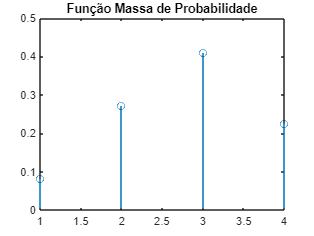

stem(xi,p);
title('Função Massa de Probabilidade');

b)  Estime o valor esperado, a variância e o desvio padrão de X com base em px(x)

*Valor esperado*

vlr_esperado = xi * p.';
fprintf("Valor esperado: %f", vlr_esperado);

Valor esperado: 2.762030

*Variância*

var = xi.^2 * p.' - vlr_esperado^2;
fprintf("Variância: %f", var);

Variância: 0.850980

*Desvio padrão*

desvio = sqrt(var);
fprintf("Desvio padrão: %f", desvio);

Desvio padrão: 0.922486

c) Identifique o tipo da distribuição da variável aleatória X e escreva a expressão teorica da respetiva função de probabilidade

% Tipo de Distribuição = Binomeal
% E[x] = n*p